# Perturbation theory for 2 Schlogl

clear all
lattice_edge = 1; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_1"


%rate constants
kdif = 0.15;    %diffusion
r01 = 6;    
r10 = 11;
r23 = 6;
r32 = 1;

Schlogl_1D_lattice
plotnam = string(lattice_edge)+"-Schlogl"

plotnam = "1-Schlogl"

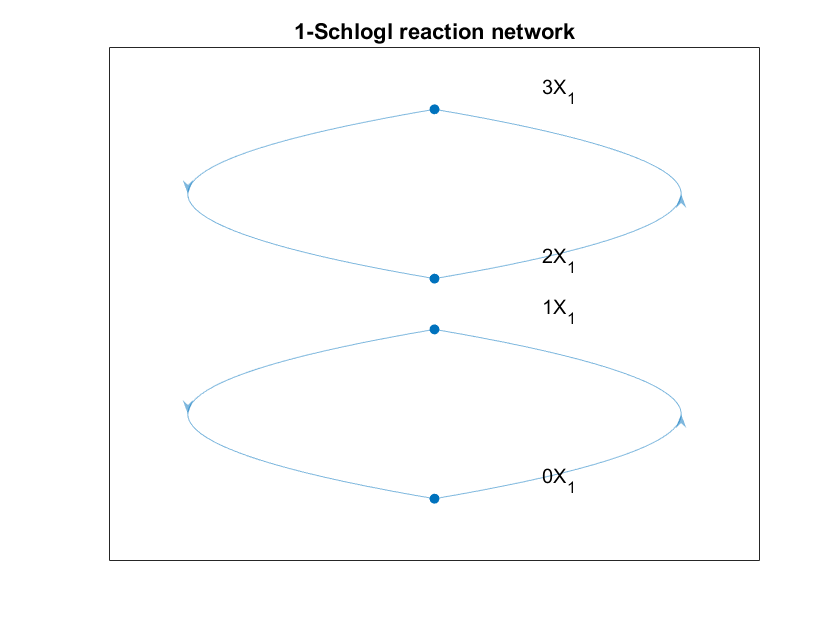

Hypergraph_plotter

Extract_Hamiltonian

$$Ham = \left({\mathrm{e}}^{-p_{1}}-1\right)\,{q_{1}}^{3}+\left(6\,{\mathrm{e}}^{p_{1}}-6\right)\,{q_{1}}^{2}+\left(11\,{\mathrm{e}}^{-p_{1}}-11\right)\,q_{1}+6\,{\mathrm{e}}^{p_{1}}-6$$

$$Eqns = \left(\frac{1}{z_{1}}-1\right)\,{q_{1}}^{3}+\left(6\,z_{1}-6\right)\,{q_{1}}^{2}+\left(\frac{11}{z_{1}}-11\right)\,q_{1}+6\,z_{1}-6=0$$

Ham

$$Ham = \left({\mathrm{e}}^{-p_{1}}-1\right)\,{q_{1}}^{3}+\left(6\,{\mathrm{e}}^{p_{1}}-6\right)\,{q_{1}}^{2}+\left(11\,{\mathrm{e}}^{-p_{1}}-11\right)\,q_{1}+6\,{\mathrm{e}}^{p_{1}}-6$$

h= 0;
p_sol = solve(Ham==h,p)

$$p\_sol = \left(\begin{array}{c} \log\left(\frac{{q_{1}}^{3}+11\,q_{1}}{6\,{q_{1}}^{2}+6}\right)\\ 0 \end{array}\right)$$

p_h = subs(p,p_sol)

$$p\_h = \left(\begin{array}{c} \log\left(\frac{{q_{1}}^{3}+11\,q_{1}}{6\,{q_{1}}^{2}+6}\right)\\ 0 \end{array}\right)$$

p_h(1)

$$ans = \log\left(\frac{{q_{1}}^{3}+11\,q_{1}}{6\,{q_{1}}^{2}+6}\right)$$

dHamdp_fun([0, 1])

ans =     2528/155   


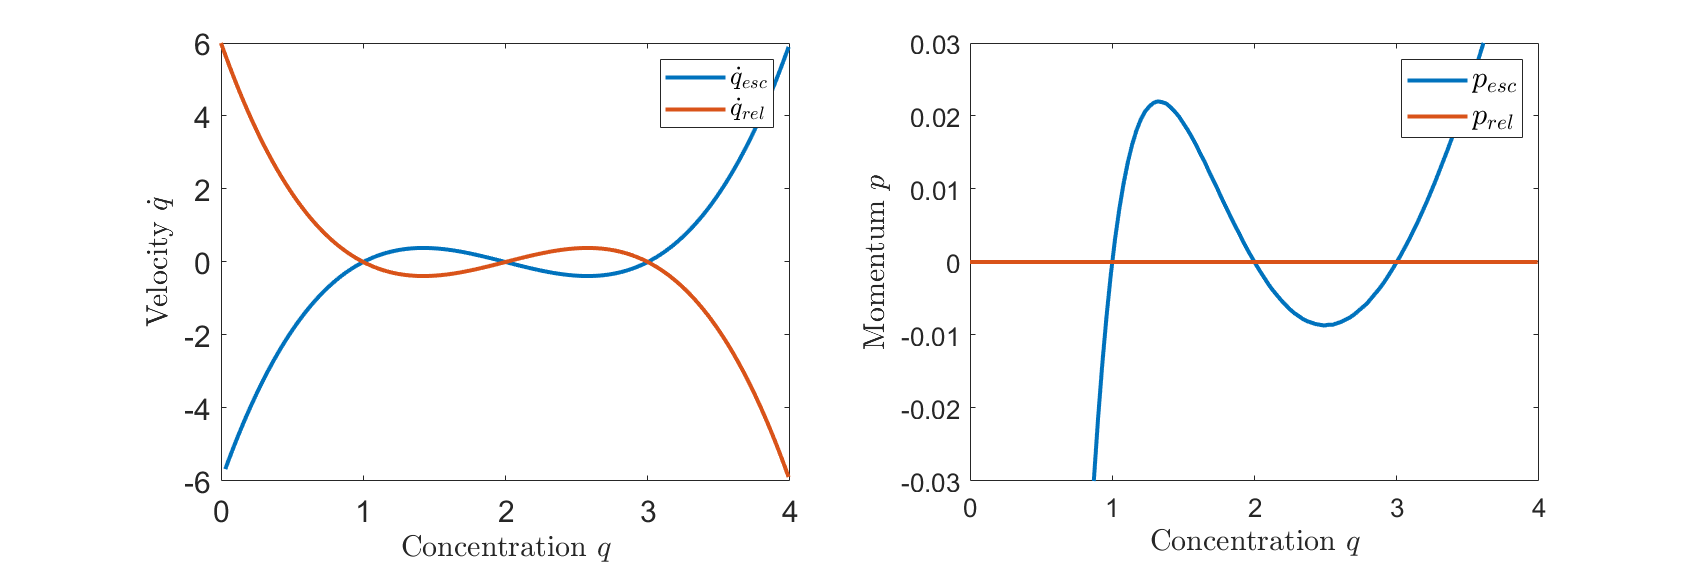

q_ran = [0:0.03:4]';
figure()
subplot(1,2,1)
plot(q_ran,dHamdp_fun([q_ran,subs(p_h(1),q,q_ran)]),'DisplayName','$\dot{q}_{esc}$','LineWidth',2)
hold on
plot(q_ran,dHamdp_fun([q_ran,subs(p_h(2),q,q_ran)]),'DisplayName','$\dot{q}_{rel}$','LineWidth',2)
hold off
ax=gca;
ax.FontSize = 15;
xlabel('Concentration $q$','Interpreter',"latex",'FontSize',15)
ylabel('Velocity $\dot{q}$','Interpreter',"latex",'FontSize',15)
h1 = legend('location','northeast');
set(h1,'Interpreter','latex');
h1.FontSize = 13;

subplot(1,2,2)
plot(q_ran,subs(p_h(1),q,q_ran),'DisplayName','$p_{esc}$','LineWidth',2)
hold on
plot(q_ran,subs(p_h(2),q,q_ran),'DisplayName','$p_{rel}$','LineWidth',2)
hold off
ax=gca;
ax.FontSize = 13;
xlabel('Concentration $q$','Interpreter',"latex",'FontSize',15)
ylabel('Momentum $p$','Interpreter',"latex",'FontSize',15)
h1 = legend('location','northeast');
set(h1,'Interpreter','latex');
h1.FontSize = 15;
ylim([-0.03,0.03])

x0=0.1;
y0=0.1;
width=30;
height=10;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])

save_plot_name = 'Schlogl_1_velocity_mom.png';
saveas(gcf,save_plot_name)

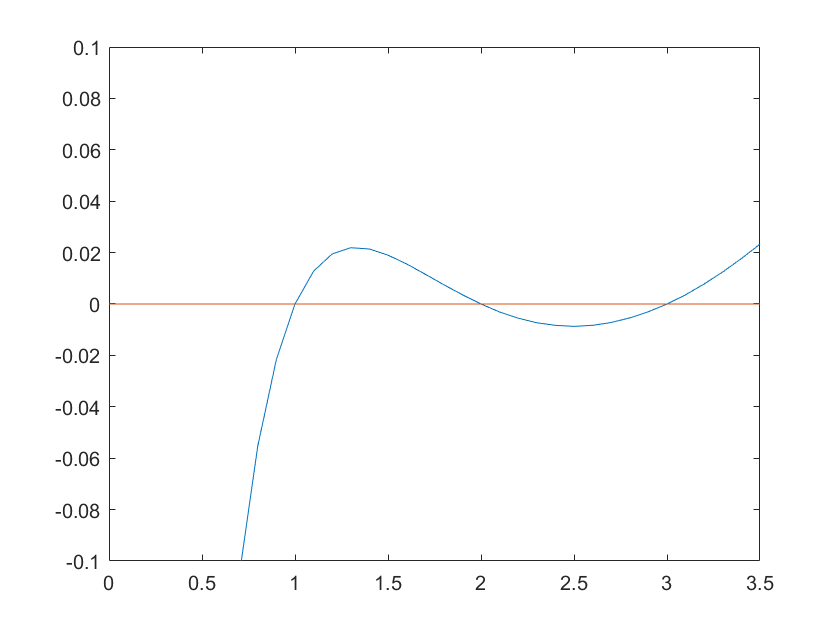

figure()
plot(q_ran,subs(p_h(1),q,q_ran))
hold on
plot(q_ran,subs(p_h(2),q,q_ran))
hold off
ylim([-0.1,0.1])